# Mobility framework

## Rigid Quadruped

We refer back to our previous work: [Geometric Mechanics of Nonslip Contact in a Planar Quadruped](https://arxiv.org/abs/2308.14357), where using a single level-set around the origin of the continuous shape subspace decoupled through shared stance, we tuned subgaits to achieve complicated average locomotion control and steering through a two-beat trot gait.

Here, using the mobility framework and discrete CCFs/stratified panels, we want to show that gait controllability is guaranteed.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
load(dataName); load(dataMotPlanName);

### Slipping coordinates

siIdx = 5; % choose legs 1 and 3 for the first contact state 
% this happens to FR and HL legs in stance during a trot gait
% this stance phase belongs to which two-beat gait?
% ... we know this is trot, but here's a programmatic way to obtain the
% ... same, helps automate most of the gait design process
[siRow, siCol] = find(kin.cs_IdxFor2bGaits == siIdx);
sjRow = siRow; % the row remains the same

% if plots are not needed, switch them off
% ... check this every section if it needs to be redefined
plotF = false; % true % false

% switch the column for the other stance phase
% ... we ensure that the ordering is as specified in the 
switch siCol, case 1, sjCol = 2; case 2, siCol = 1; sjCol = 2; end

% stance phases i and j and the corresponding legs are given below
cs_i = kin.cs( kin.cs_IdxFor2bGaits(siRow, siCol), : )

cs_i =      1     3


cs_j = kin.cs( kin.cs_IdxFor2bGaits(sjRow, sjCol), : )

cs_j =      2     4


The way this is setup so that you can choose the submanifolds in any order and the result doesn't switch the ordering.

Let's choose the first submanifold in a trot gait first.

sIdx = kin.cs_IdxFor2bGaits(siRow, siCol);

Exploring the continuous shape subspace of stancing limbs in the current level-2 submanifold.

% unpack the limb length ratio `a' and body length parameter `l'
% ... given `l', the limb length is defined as `a' in the range of (0, 1]
% ... `l' is the x and y offset needed to reach any hip joint frame ($h_ib$)
% ... from the body centroid/COM, ($h_b$)
a = kinfunc{sIdx}.aa;
l = kinfunc{sIdx}.aa;

% get the integration limits
alphaLimits = [p_info{sIdx}.xlimits;
                p_info{sIdx}.ylimits] 

alphaLimits =    -1.5708    1.5708
   -1.5708    1.5708


alphaBox = get2boxFromLimits(alphaLimits);
% this is a constant limit, doesn't change between limbs

% the continuous shape subspace
% ... continuous because we aren't considering discrete contact shape,
% ... \beta at the moment
% ... this will help us extract the zero contour of the \theta-panel 
ai = p_kin{sIdx}.ai; aj = p_kin{sIdx}.aj;

% Salient points .................................................. %
% explore the entire limb angle range to find the singularities
% ... these singularities occur at extremal values of F
% ... take the ranges of both limb angles to be +-pi
% ... we shall use `fmincon' to identify these points
% ... also, since we need the function to compute F, we shall store that
% ... instead of calling it from struct every single time (give
% ... brain-damage bruh, trust me!)
% ................................................................. %

% for our initial analysis, we shall consider the origin as a constant
% reference point
refPtOrg = zeros(1, 2);

% unpack the functions needed
% ... squared, inter-leg distance for the stancing feet
F_fxnNow = kin.ksq_ij{sIdx};

% the contracting singularity when the stancing legs are closest to each
% other
% ... we minimize F for this directly
aInf = fmincon(@(x) F_fxnNow(a, l, x(1), x(2)), ... % set fixed a and l, and iterate over x
                refPtOrg, [], [], [], [], ... % ic for limb angles at the origin
                -pi*ones(1, 2), pi*ones(1, 2)); % bounds for the unlocked limb angles


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% ... corresponding F value
F_inf = F_fxnNow(a, l, aInf(1), aInf(2))

F_inf = 0.6863


% the expanding singularity when the stancing legs are the farthest away
% from each other
% ... we maximize F indirectly by minimizing -F
aSup = fmincon(@(x) -F_fxnNow(a, l, x(1), x(2)), ...
                refPtOrg, [], [], [], [], ... 
                -pi*ones(1, 2), pi*ones(1, 2));


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


F_sup = F_fxnNow(a, l, aSup(1), aSup(2))

F_sup = 23.3137

% Remove all F-levels that are within a certain neighborhood of the
% singularities by setting percentage bounds on the F-levels
% ... let's try different ranges and see what works best for us
F_range  = F_sup - F_inf;
prctRm = 2; % SET PERCENTAGE FOR BOUNDS HERE
F_bounds = prctRm/100*F_range*[+1 -1] + [F_inf F_sup]; % pull the bounds inwards

% the squared inter-leg distance as a function of the continuous shape
% subspace
% ... from the 'p_kin' struct, we obtain the sweep as a function of ai and
% ... aj, and plot it as contours for reference.
% ... we also obtain the corresponding colormap from 'p_info' struct to
% ... keep things standardized
ksq_sweep = p_kin{sIdx}.ksq_sweep;
jetDark = p_info{sIdx}.jetDark;

% obtain the full range of F and the corresponding coordinates as sweeps
aiF          = linspace(-pi, pi, size(ai, 1));
ajF          = linspace(-pi, pi, size(aj, 1));
[aiF, ajF]   = meshgrid(aiF, ajF);
F_sweep_full = F_fxnNow(a, l, aiF, ajF);

% obtain the indices of the sweep that do not satisfy our prescribed bounds 
% and set the corresponding sweep values to NaN
idxNotBounded = (F_sweep_full < F_bounds(1) | F_sweep_full > F_bounds(2));
F_sweep_full_bounded = F_sweep_full; F_sweep_full_bounded(idxNotBounded)= nan;
idxNotBounded = (ksq_sweep < F_bounds(1) | ksq_sweep > F_bounds(2));
ksq_sweep_bounded = ksq_sweep; ksq_sweep_bounded(idxNotBounded) = nan;


% obtain the extremal colors for plotting the locations of supremum and
% infimum of F
aInfCol = interpColorAndCondition...
    (   linspace(F_inf, F_sup, size(jetDark, 1)), jetDark, F_inf   );
aSupCol = interpColorAndCondition...
    (   linspace(F_inf, F_sup, size(jetDark, 1)), jetDark, F_sup   );

if plotF
    % Let's visualize the supremum and infimum of F and its location
    TL = tiledlayout('horizontal', 'TileSpacing', 'tight', 'Padding', 'tight');
    figure;
    
    ax = nexttile(TL); % full F
    contour(ax, aiF, ajF, F_sweep_full, 25, 'LineWidth', 0.05);
    hold(ax, "on"); grid(ax, "on");
    scatter(ax, aInf(1), aInf(2), 100, aInfCol, "filled", "square");
    scatter(ax, aSup(1), aSup(2), 100, aSupCol, "filled", "o");
    quiver(ax, alphaBox.X, alphaBox.Y, alphaBox.U, alphaBox.V, "off",...
        'ShowArrowHead', 'off', 'LineWidth', 1.2, 'LineStyle', ':',...
        'Color', 'r', 'DisplayName', 'Accessible Shape Space'); % plot the accessible shape space bounding box
    xlim(ax, pi*[-1, 1]); ylim(ax, pi*[-1, 1]); 
    colormap(ax, jetDark); clim(ax, [F_inf F_sup]);
    title(ax, 'Unbounded F'); axis(ax, "equal", "square");
    
    ax = nexttile(TL); % bounded F
    contour(ax, aiF, ajF, F_sweep_full_bounded,...
        25, 'LineWidth', 0.05, 'DisplayName', "F-contours");
    hold(ax, "on"); grid(ax, "on");
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(1), F_bounds(1)], '--',...
        'LineWidth', 1.2, 'Color', aInfCol, 'DisplayName', "Lower bound"); % lower bound of F
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(2), F_bounds(2)], '--',...
        'LineWidth', 1.2, 'Color', aSupCol, 'DisplayName', "Upper bound"); % upper bound of F
    scatter(ax, aInf(1), aInf(2), 100, aInfCol,...
        "filled", "square", "DisplayName", "Infimum");
    scatter(ax, aSup(1), aSup(2), 100, aSupCol,... % still plot the supremum and infimum pts for ref
        "filled", "o", "DisplayName", "Supremum");
    quiver(ax, alphaBox.X, alphaBox.Y, alphaBox.U, alphaBox.V, "off",...
        'ShowArrowHead', 'off', 'LineWidth', 1.2, 'LineStyle', ':',...
        'Color', 'r', 'DisplayName', 'Accessible Shape Space');
    legend("Location", "northoutside"); 
    xlim(pi*[-1, 1]); ylim(pi*[-1, 1]);
    colormap(jetDark); clim([F_inf F_sup]); 
    cb = colorbar(); cb.Layout.Tile = "south";
    title('Bounded F'); axis(ax, "equal", "square");
    drawnow(); set(gcf, 'Visible', 'on');
end

Call a function that checks if the limb angle solution are within desired `F_bounds' and angle bounds of the shape subspace as those are the only solutions we can use. For more details and to add additional ode EVENTs check ''Utility Functions\nonslipShapeCoordsEvents.m".

% initialize and define an argument structure
% ... we shall use the parameters, bounds, and functions needed by our
% ... event function to check for violation of shape-space/F-bounds
argStruct = []; 
argStruct.parameters = []; argStruct.bounds = []; argStruct.functions = [];
argStruct.parameters.a = a; argStruct.parameters.l = l;
argStruct.bounds.alphaLimits = alphaLimits; argStruct.bounds.F_bounds = F_bounds;
argStruct.functions.F_fxn = F_fxnNow;
% generate the two events needed
% ... we need the 'shape_bounds' and 'F_bounds' event
eventList = {'shape_bounds', 'F_bounds'};

Now, we need to obtain the path along the gradient of $F$ passing through the origin and doesn't hit the bounds for level-sets we computed earlier. The easiest way I can think of doing this is to setup ode89 along the gradient directions with a stopping event when the bounds are violated.

Another stopping event needs requires a min forward and backward integration length of $1.2$ about the refernce point. This also needs to be baked in into the formulation below. Note that this would be an integration at each point along level-sets of $F$.

% get the function to compute gradients
gradF_dirn_now = kin.dksq_dirn_ij{sIdx};

% intialize a structure to hold all the solutions
gradFIntegralCurve = []; % parent structure to hold all the integral curve information
gradFIntegralCurve.odeOptions = []; % initialize the integration options
gradFIntegralCurve.fwd_soln = []; gradFIntegralCurve.bwd_soln = [];

% setup the options for integration
gradFIntegralCurve.odeOptions = odeset('Events', @(t, y) nonslipShapeCoordsEvents(t, y, argStruct, eventList));

Now that we have the event function setup and a way to stop once we connect forward and backward on closed level-sets that are within allowable $F$-bounds, we now just need to integrate forward and backward from the origin.

[tNow, yNow, teNow, yeNow, ieNow] = ...
    ode89( @(t, y) +gradF_dirn_now(a, l, y(1), y(2)), ... % run the states into the gradient direction as the velocity
            [0 25], ... % time-span, it should be large enough to reach the F or shape space bounds (play around with it!)
            refPtOrg, ... % we are always going to start at the origin, unless its outside the Fbounds.
            gradFIntegralCurve.odeOptions ); % pass the bound violation events we setup earlier
tFwd = teNow; yFwd = yeNow;
yNow = yNow(tNow <= tFwd, :);
tNow = tNow(tNow <= tFwd); % edit solution until event, nothing changes if no event
gradFIntegralCurve.fwd_soln.t  = tNow;
gradFIntegralCurve.fwd_soln.y  = yNow;
gradFIntegralCurve.fwd_soln.te = teNow;
gradFIntegralCurve.fwd_soln.ye = yeNow;
gradFIntegralCurve.fwd_soln.ie = ieNow;

if plotF
    % plot the backward solution
    figure; ax = gca;
    contour(ai, aj, ksq_sweep_bounded, 25, 'LineWidth', 0.05,...
        'DisplayName', "F-contours");
    hold(ax, "on"); grid(ax, "on");
    plot(ax, yNow(:, 1), yNow(:, 2), 'k-', 'LineWidth', 1.2,...
        "DisplayName", "backward gradF path");
    scatter(ax, yNow(end, 1), yNow(end, 2), 100, [227,74,51]/255,...
        "filled", "square", "DisplayName", "stop");
    scatter(ax, refPtOrg(1), refPtOrg(2), 100, [67,162,202]/255,...
        "filled", "o", "DisplayName", "reference point");
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(1), F_bounds(1)], '--',...
        'LineWidth', 1.2, 'Color', aInfCol, 'DisplayName', "Lower bound"); % lower bound of F
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(2), F_bounds(2)], '--',...
        'LineWidth', 1.2, 'Color', aSupCol, 'DisplayName', "Upper bound"); % upper bound of F
    scatter(ax, aInf(1), aInf(2), 100, aInfCol,...
        "filled", "square", "DisplayName", "Infimum");
    scatter(ax, aSup(1), aSup(2), 100, aSupCol,... % still plot the supremum and infimum pts for ref
        "filled", "o", "DisplayName", "Supremum");
    % legend("Location", "bestoutside"); 
    colormap(jetDark); clim([F_inf F_sup]); colorbar(ax, "northoutside");
    xlim(alphaLimits(1, :)); ylim(alphaLimits(2, :)); axis(ax, "square");
    drawnow(); set(gcf, 'Visible', 'on');
end

We stopping in like 0.2 shape space length units (obviously under a unity metric), which is quite quick and implies that the origin was already pretty close to the $F$-bounds we computed earlier.

The backward solution:

[tNow, yNow, teNow, yeNow, ieNow] = ...
    ode89( @(t, y) -gradF_dirn_now(a, l, y(1), y(2)), ... % negate the gradient direction to integrate backwards
            [0 25], ... 
            refPtOrg, ... 
            gradFIntegralCurve.odeOptions );
tBwd = teNow;
yNow = yNow(tNow <= tBwd, :);
tNow = tNow(tNow <= tBwd);
gradFIntegralCurve.bwd_soln.t  = tNow;
gradFIntegralCurve.bwd_soln.y  = yNow;
gradFIntegralCurve.bwd_soln.te = teNow;
gradFIntegralCurve.bwd_soln.ye = yeNow;
gradFIntegralCurve.bwd_soln.ie = ieNow;

Now, we obtain the range of different F-levels by starting at the event location of the backward solution and integrating all the way forward with sum of the forward and backward event times.

tMain = tFwd + tBwd;                                      % for the main solution, we integrate for the total length
gradFIntegralCurve.main_soln = [];                        % initialize the solution struct
[tNow, yNow, teNow, yeNow, ieNow] = ...
    ode89( @(t, y) -gradF_dirn_now(a, l, y(1), y(2)), ... % negate the gradient direction to integrate backwards from the final forward position
            linspace(0, tMain, size(ai, 1)), ...          % integrate for the total event duration to get to the other end
            yFwd, ...                                     % end of the forward integration or first fwd event as the initial condition 
            gradFIntegralCurve.odeOptions );
gradFIntegralCurve.main_soln.t  = tNow;                   % store this solution for later use
gradFIntegralCurve.main_soln.y  = yNow;
gradFIntegralCurve.main_soln.te = teNow;
gradFIntegralCurve.main_soln.ye = yeNow;
gradFIntegralCurve.main_soln.ie = ieNow;

if plotF
    % plot the full solution
    figure; ax = gca;
    contour(ai, aj, ksq_sweep_bounded, 25, 'LineWidth', 0.05,...
        'DisplayName', "F-contours");
    hold(ax, "on"); grid(ax, "on");
    plot(ax, yNow(:, 1), yNow(:, 2), 'k-', 'LineWidth', 1.2,...
        "DisplayName", "full gradF path");
    scatter(ax, yNow(1, 1), yNow(1, 2), 100, [227,74,51]/255,...
        "filled", "o", "DisplayName", "start");
    scatter(ax, yNow(end, 1), yNow(end, 2), 100, [227,74,51]/255,...
        "filled", "square", "DisplayName", "stop");
    scatter(ax, refPtOrg(1), refPtOrg(2), 100, [67,162,202]/255,...
        "filled", "o", "DisplayName", "reference point");
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(1), F_bounds(1)], '--',...
        'LineWidth', 1.2, 'Color', aInfCol, 'DisplayName', "Lower bound"); % lower bound of F
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(2), F_bounds(2)], '--',...
        'LineWidth', 1.2, 'Color', aSupCol, 'DisplayName', "Upper bound"); % upper bound of F
    scatter(ax, aInf(1), aInf(2), 100, aInfCol,...
        "filled", "square", "DisplayName", "Infimum");
    scatter(ax, aSup(1), aSup(2), 100, aSupCol,... % still plot the supremum and infimum pts for ref
        "filled", "o", "DisplayName", "Supremum");
    % legend("Location", "bestoutside"); 
    colormap(jetDark); clim([F_inf F_sup]); colorbar(ax, "northoutside");
    xlim(alphaLimits(1, :)); ylim(alphaLimits(2, :)); axis(ax, "square");
    drawnow(); set(gcf, 'Visible', 'on');
end

With this main solution, we have obtained the slipping coordinate of the nonslip-slip coordinate system and as this coordinate is perpendicular to our nonslip level-sets over which the stance phase paths are described, we shall denote it as ${\Delta \alpha}^{\perp}_{i}$. Correspondingly, the nonslip directions will be ${\Delta \alpha}^{\parallel}_{i}$. In both symbols, `$i$' denotes the current stance phase or subgait index.

Next, we need to identify the shape space paths at different level-sets of $F$. In the aforementioned previous work, we used forward and backward integration length of 1.2 and we shall further restrict the level-sets based on this availability along the $\Delta F$ integral curve (satisfying pre-determined bounds).

% get the function to integrate along the level-sets of F
gradF_perpDirn_now = matlabFunction(kinfunc{sIdx}.dpsi, "Vars", [sym("a"), sym("l"),...
    sym(['alpha_' num2str(cs_i(1))]),...
    sym(['alpha_' num2str(cs_i(2))]) ]);

% get the current F value at the reference point    
Fnow = F_fxnNow(a, l, refPtOrg(1), refPtOrg(2));

% get the current F level-sets' color
cMapNow = jetDark;
colNow = interpColorAndCondition(  ... % interpolate
    linspace(F_inf, F_sup, size(cMapNow, 1)), cMapNow, Fnow...
                                );

% integrate and obtain the two endpoints to define the accessible level-set
% ... 1) integrate backward and obtain the ic from reference to integrate
% ... forward
integration_time = 1.2*ones(1, 2); % [backward, forward] integration lengths
[~, yNow] = ode89( @(t,y) -gradF_perpDirn_now(a, l, y(1), y(2)), ...
    [0, integration_time(1)], refPtOrg ); 

if plotF
    figure; ax = gca;
    contour(ai, aj, ksq_sweep_bounded, 25, 'LineWidth', 0.05,...
        'DisplayName', "F-contours");
    hold(ax, "on"); grid(ax, "on");
    plot(ax, yNow(:, 1), yNow(:, 2), 'k-', 'LineWidth', 1.2,...
        "DisplayName", "backward F path"); % "Color", colNow, 
    scatter(ax, yNow(end, 1), yNow(end, 2), 100, [227,74,51]/255,...
        "filled", "square", "DisplayName", "stop");
    scatter(ax, refPtOrg(1), refPtOrg(2), 100, [67,162,202]/255,...
        "filled", "o", "DisplayName", "reference point");
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(1), F_bounds(1)], '--',...
        'LineWidth', 1.2, 'Color', aInfCol, 'DisplayName', "Lower bound"); % lower bound of F
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(2), F_bounds(2)], '--',...
        'LineWidth', 1.2, 'Color', aSupCol, 'DisplayName', "Upper bound"); % upper bound of F
    scatter(ax, aInf(1), aInf(2), 100, aInfCol,...
        "filled", "square", "DisplayName", "Infimum");
    scatter(ax, aSup(1), aSup(2), 100, aSupCol,... % still plot the supremum and infimum pts for ref
        "filled", "o", "DisplayName", "Supremum");
    % legend("Location", "bestoutside"); 
    colormap(jetDark); clim([F_inf F_sup]); colorbar(ax, "northoutside");
    xlim(alphaLimits(1, :)); ylim(alphaLimits(2, :)); axis(ax, "square");
    drawnow(); set(gcf, 'Visible', 'on');
end
% ... 2) integrate forward to the presribed end based on integration length
[~, yNow] = ode89( @(t,y) gradF_perpDirn_now(a, l, y(1), y(2)), ...
    linspace(0, sum(integration_time), size(ai, 1)), yNow(end, :) );

if plotF
    figure; ax = gca;
    contour(ai, aj, ksq_sweep_bounded, 25, 'LineWidth', 0.05,...
        'DisplayName', "F-contours");
    hold(ax, "on"); grid(ax, "on");
    plot(ax, yNow(:, 1), yNow(:, 2), 'k-', 'LineWidth', 1.2,...
        "DisplayName", "full F path"); % "Color", colNow, 
    scatter(ax, yNow(1, 1), yNow(1, 2), 100, [227,74,51]/255,...
        "filled", "o", "DisplayName", "start");
    scatter(ax, yNow(end, 1), yNow(end, 2), 100, [227,74,51]/255,...
        "filled", "square", "DisplayName", "stop");
    scatter(ax, refPtOrg(1), refPtOrg(2), 100, [67,162,202]/255,...
        "filled", "o", "DisplayName", "reference point");
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(1), F_bounds(1)], '--',...
        'LineWidth', 1.2, 'Color', aInfCol, 'DisplayName', "Lower bound"); % lower bound of F
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(2), F_bounds(2)], '--',...
        'LineWidth', 1.2, 'Color', aSupCol, 'DisplayName', "Upper bound"); % upper bound of F
    scatter(ax, aInf(1), aInf(2), 100, aInfCol,...
        "filled", "square", "DisplayName", "Infimum");
    scatter(ax, aSup(1), aSup(2), 100, aSupCol,... % still plot the supremum and infimum pts for ref
        "filled", "o", "DisplayName", "Supremum");
    % legend("Location", "bestoutside"); 
    colormap(jetDark); clim([F_inf F_sup]); colorbar(ax, "northoutside");
    xlim(alphaLimits(1, :)); ylim(alphaLimits(2, :)); axis(ax, "square");
    drawnow(); set(gcf, 'Visible', 'on');
end

This is very similar to the *trial* case stance path from our previous work.

Moving forward, we shall atleast require this much ``space" (integration length of $1.2$ on forward and backward paths) in the current $F$ level-set.

### Nonslip coordinates

To compute the level-set solutions, we first create an event function similar to the last one with shape-space bounds. 

But, unlike the last one, we also add a check to see if the level-set has connected on itself. 

This is a two-step process:

- For the current reference point, we obtain a long forward and backward trajectory and check which extremal point is the centroid.

- Then, we setup the options for the actual integration where the second event ends up being the phase check to see if the requested path connects on itself.

- Finally, we obtain the forward and backward paths and check to see if the phases ever exceed the reference phase plus or minus $180^{\circ}$ $(p_0 \pm \pi)$. We set this up as a terminal direction independent ODE event-- this is because the integration times on either side of the reference point are equal. So, the same check should work.

**Update 2024/06/20:** This EVENT function is now appended to the "nonslipShapeCoordsEvents.m" function in the `Utility Functions' folder. So, below we just update the argument structure and the list of events needed for the current integration.

To verify the *phase-restricted* ODE integration, we first need to obtain reliable centroid information. Given that the level-sets contain one of the singularities or extremal values of $F$, the goal is to classify the current level-sets centroid to one or the other.

- Obtain the forward and backward trajectories for a long integration length (using 100 right now).

- Obtain the error between the points along this path and the singularities.

- The smallest mean error with respect to a singularity outputs that sinfularity as the centroid.

Once we have the centroid, we can then compute the phase of the reference point and obtain all the other phases as described in the event function above.

% choose a reference point
% ... we look at one of the level-sets where we can find the full solution
% ... that connects back on itself-- one of these solutions happens when
% ... both limb angles are ~35 degrees (~0.6 radians)--
% ... another example we look at is the F-lvl at the edge of the accessible
% ... shape space-- works well now.
y0now = 0.6*ones(1, 2);
% y0now = gradFIntegralCurve.main_soln.y(end, :);

% choose an integration time
% ... this has to be sufficiently large to accommodate the shift towards
% ... one of the extremal values
tInt = 100*[1 1]; % keeping forward and backward passes uniform as usual

% compute the extremal point and the phase of the current reference
% point %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ... we use coarse approximations for this solve using 'ode23'
% ... function
% ... first ode solver call would be for a backward pass
% ... second call is for the forward pass for twice the time from the
% ... end of the backward pass
% ... infimum of the error selects one of the extremal points as the
% ... centroid if we integrate for sufficiently long
[~, yNow] = ode23(@(t, y) -gradF_perpDirn_now(a, l, y(1), y(2)),...
    [0 tInt(1)], y0now);
[~, yNow] = ode23(@(t, y) +gradF_perpDirn_now(a, l, y(1), y(2)),...
    [0 sum(tInt)], yNow(end, :));
% compute the error wrt to the extremal points
errInf = repmat(aInf, size(yNow, 1), 1) - yNow; errInf = min(vecnorm(errInf, 2, 2));
errSup = repmat(aSup, size(yNow, 1), 1) - yNow; errSup = min(vecnorm(errSup, 2, 2));
% get the extremal point (or centroid) location and then the error of
% the reference point
switch errInf < errSup
    case 1
        yExtremal = aInf; 
    case 0
        yExtremal = aSup; % required centroid/extremal point
end
phasorNow = (y0now - yExtremal)/norm(y0now - yExtremal); 
yRefPhase = atan2(phasorNow(2), phasorNow(1)); % required phase

Let's visualize this phasor and a random position with respect to the self-connecting phase (or phasor).

figure; ax = gca; axis(ax, "square", "equal", "tight");
quiver(ax, yExtremal(1), yExtremal(2), phasorNow(1), phasorNow(2),...
    "off", 'LineWidth', 1.2, 'Color', 'k');
hold(ax, "on"); grid(ax, "on");
scatter(ax, yExtremal(1), yExtremal(2), 25, 'k', 'filled');
y = rand(2, 1); yPhasor = (y - yExtremal)/norm(y - yExtremal); 
yPhase = atan2(yPhasor(2), yPhasor(1))

yPhase = -2.9370

yPhase_Deg = rad2deg(yPhase)

yPhase_Deg = -168.2774

ySO2 = rot_SE2(yPhase)

ySO2 =    -0.9791    0.2032         0
   -0.2032   -0.9791         0
         0         0    1.0000


yRefSO2 = rot_SE2(yRefPhase)

yRefSO2 =    -0.7071    0.7071         0
   -0.7071   -0.7071         0
         0         0    1.0000


ySelfConnectedSO2 = rot_SE2(pi)*yRefSO2

ySelfConnectedSO2 =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


quiver(ax, yExtremal(1), yExtremal(2), ySelfConnectedSO2(1, 1), ySelfConnectedSO2(2, 1),...
    "off", 'LineWidth', 1.2, 'Color', 'k', 'LineStyle', '--');
yDiffSO2 = ySO2*ySelfConnectedSO2'

yDiffSO2 =    -0.8360   -0.5487         0
    0.5487   -0.8360         0
         0         0    1.0000


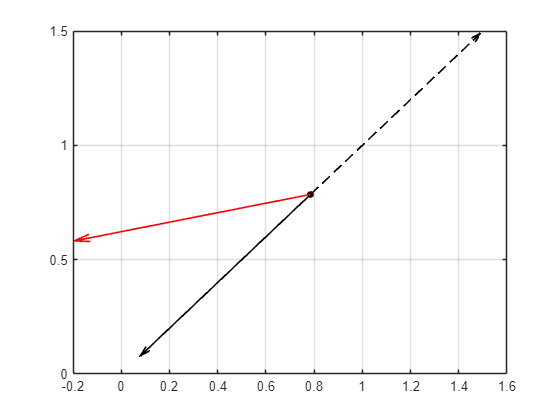

quiver(ax, yExtremal(1), yExtremal(2), ySO2(1, 1), ySO2(2, 1),...
    "off", 'LineWidth', 1.2, 'Color', 'r');

yDiffCos = ( yDiffSO2(1, 1) + yDiffSO2(2, 2) )*0.5;
yDiffSin = (-yDiffSO2(1, 2) + yDiffSO2(2, 1) )*0.5;
yDiff = atan2(yDiffSin, yDiffCos)

yDiff = 2.5608

yDiff_Deg = rad2deg(yDiff)

yDiff_Deg = 146.7226

This seems to be the correct way of finding the angle of the current solution from the self-connection point.

Next, we need to verify the stopping criteria for self-connecting level-sets of $F$ as we integrate to obtain solutions. To that effect, we update our events function call and the related arguments and event list variables based on the phase bounds condition we tested earlier.

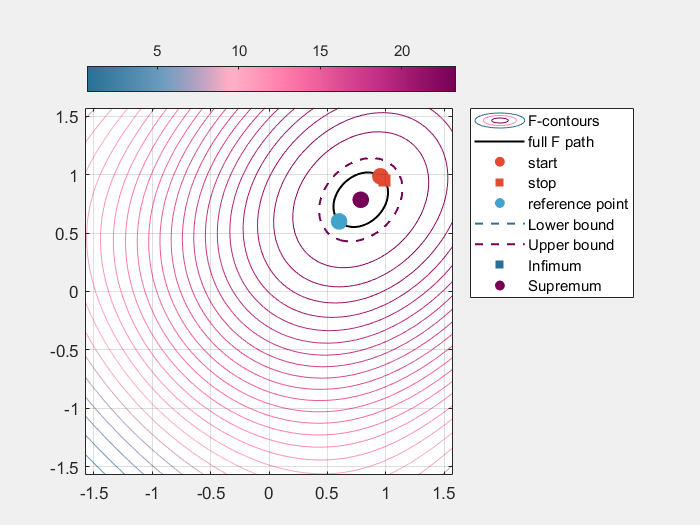

% plot the final result
plotF = true;

% choose a flag to record if the current trajectory is valid and use an
% event information string to hold the type of termination event as a
% string for later use
% ... we set this by default true, and if the total integration length is
% ... not met, then we set it to false later
% ... since the trajectory is defaultly valid, the 'eventInfo' cell array 
% ... is empty by default
validFlag = true;
eventInfo = cell(1, 2);

% updated arguments and events list
% ... the angle threshold is defined in the reference of yRefPhase+\pi
% ... where the F level-set solution would connect on itself. So, the
% ... threshold value would add a margin of +-threshold about yRefPhase+\pi
% ... to prevent the self-connectedness from showing up.
% ... 
argStruct.bounds.angleThreshold = deg2rad(5); % SET ANGLE THRESHOLD HERE
% ... 
% ... updated the parameters and bounds for our phase-based, self-connected
% ... F level-sets event
argStruct.parameters.yExtremal = yExtremal;
argStruct.parameters.yRefPhase = yRefPhase;

eventList = {'shape_bounds', 'phase_bounds'};

% main solution %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ... set the options based on the location of the extremal point and
% ... the current phase
% ... perform the forward and backward integration of the requested
% ... integration length of 1.2
% ... if the length could not be achieved because of out of bounds in
% ... shape space or phase constraints (self-connected F level-set
% ... violation), safe the valid flag as false and exit
% set the integration options
optionsNow = odeset(  ...
                    'Events', ...
    @(t, y) nonslipShapeCoordsEvents(t, y, argStruct, eventList) ...
                    );
% forward and backward integration to obtain the solution
% ... perform the backward integration and if the terminal event conditions
% ... were satisfied, set the validFlag to false and return
% ... based on event based stop or integration length stop, we decide the
% ... backward integration time that can be <= integration_time(1)
[tNow, yNow, teNow, ~, ieNow] = ...
    ode89( @(t,y) -gradF_perpDirn_now(a, l, y(1), y(2)), ...
    [0, integration_time(1)], y0now, optionsNow );
if isempty(teNow)
    tBwd = tNow(end);
    eventInfo{1} = '';
else
    validFlag = false; % not a valid level-set
    tBwd = teNow; ieBwd = ieNow;
    switch ieBwd
        case 1
            eventInfo{1} = 'shape bounds violation';
        case 2
            eventInfo{1} = 'self-connected sets violation';
    end
end
tMain = tBwd + integration_time(2); % modulate the integration time if an event occured 
yNow = yNow(tNow <= tBwd, :); % modulate the solution output
yIC = yNow(end, :); % get the final solution time-step as the initial condition
[tNow, yNow, teNow, yeNow, ieNow] = ...
    ode89( @(t,y) gradF_perpDirn_now(a, l, y(1), y(2)), ...
    linspace(0, tMain, size(ai, 1)),...
    yIC, optionsNow );
if isempty(teNow)
    tFull = tNow(end);
    eventInfo{2} = '';
else
    validFlag = false; % not a valid level-set
    tFull = teNow; ieFull = ieNow;
    switch ieFull
        case 1
            eventInfo{2} = 'shape bounds violation';
        case 2
            eventInfo{2} = 'self-connected sets violation';
    end
end
yFull = yNow(tNow <= tFull, :);
tFull = tNow(tNow <= tFull);

% plot of the results
if plotF
    figure; ax = gca;
    contour(ai, aj, ksq_sweep_bounded, 25, 'LineWidth', 0.05,...
        'DisplayName', "F-contours");
    hold(ax, "on"); grid(ax, "on");
    plot(ax, yFull(:, 1), yFull(:, 2), 'k-', 'LineWidth', 1.2,...
        "DisplayName", "full F path"); % "Color", colNow, 
    scatter(ax, yFull(1, 1), yFull(1, 2), 100, [227,74,51]/255,...
        "filled", "o", "DisplayName", "start");
    scatter(ax, yFull(end, 1), yFull(end, 2), 100, [227,74,51]/255,...
        "filled", "square", "DisplayName", "stop");
    scatter(ax, y0now(1), y0now(2), 100, [67,162,202]/255,...
        "filled", "o", "DisplayName", "reference point");
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(1), F_bounds(1)], '--',...
        'LineWidth', 1.2, 'Color', aInfCol, 'DisplayName', "Lower bound"); % lower bound of F
    contour(ax, aiF, ajF, F_sweep_full, [F_bounds(2), F_bounds(2)], '--',...
        'LineWidth', 1.2, 'Color', aSupCol, 'DisplayName', "Upper bound"); % upper bound of F
    scatter(ax, aInf(1), aInf(2), 100, aInfCol,...
        "filled", "square", "DisplayName", "Infimum");
    scatter(ax, aSup(1), aSup(2), 100, aSupCol,... % still plot the supremum and infimum pts for ref
        "filled", "o", "DisplayName", "Supremum");
    legend("Location", "bestoutside"); 
    colormap(jetDark); clim([F_inf F_sup]); colorbar(ax, "northoutside");
    xlim(alphaLimits(1, :)); ylim(alphaLimits(2, :)); axis(ax, "square");
    drawnow(); set(gcf, 'Visible', 'on');
end

We are able to successfully identify self-connected sets and fix that.

Next, we package this process into the new 'Path2_mobility' class.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
load(dataName); load(dataMotPlanName);

Running the 'Path2_mobility' class to compute the slip and nonslip coordinates.

submanifoldIndex = 5; % we know that FR-HL stance phase is 5
integrationTime = 1.2*ones(1, 2); % set to paper 2 params for uniformity
refPtOrg = zeros(1, 2); % choose the reference point about which to compute
                        % the slip and nonslip directions
                        % ... we defaultly choose the orgin to first
                        % ... replicate our results from Paper 2.
FRHLstance = Path2_Mobility(submanifoldIndex, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg); % compute current stance

We identify the complementary submanifold using a static method in the "Path2_Mobility" class and then automatically construct and return that object.

FLHRstance = Path2_Mobility.constructComplementaryStance...
                    (FRHLstance, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg); % compute complementary stance

Save the stance phase data.

save(dataMotPlanName, "FRHLstance", "FLHRstance", "-append");

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
load(dataName); load(dataMotPlanName);

Let's plot this new coordinates for the two contact states in a trot gait.

Path2_Mobility.visualizeNonslipLevelSets(FRHLstance)
Path2_Mobility.visualizeSlipNonslipShapeCoordinates(FRHLstance)

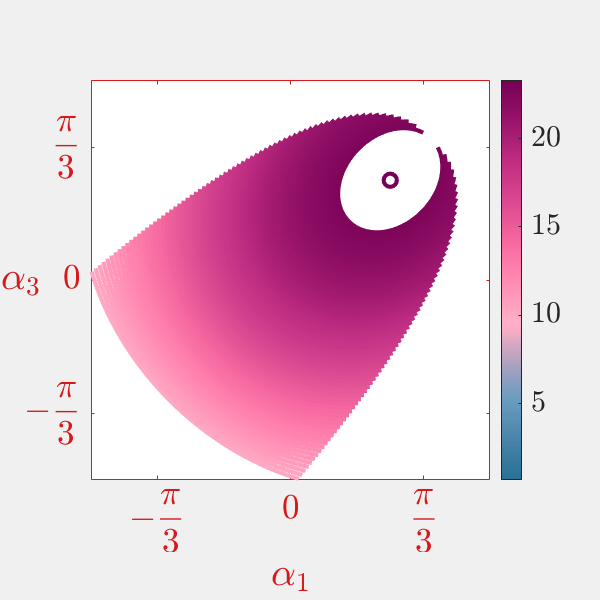

Path2_Mobility.visualizeNonslipLevelSets(FLHRstance)

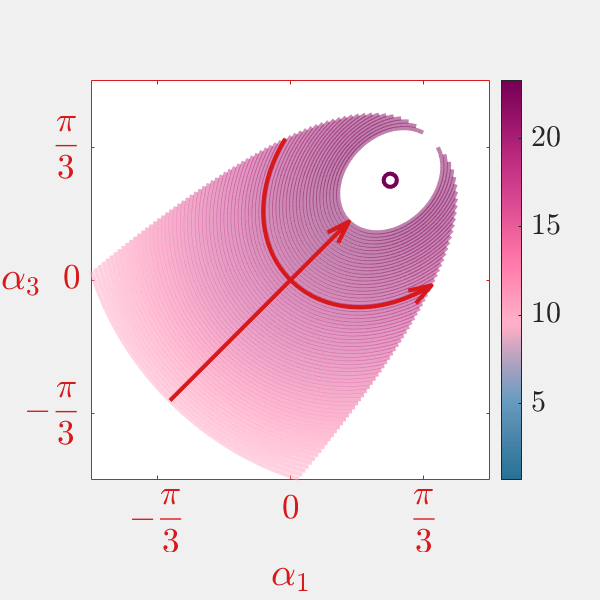

Path2_Mobility.visualizeSlipNonslipShapeCoordinates(FLHRstance)

Let's highlight the reference paths at $[0,0]$ where we shall carry out our mobility analysis.

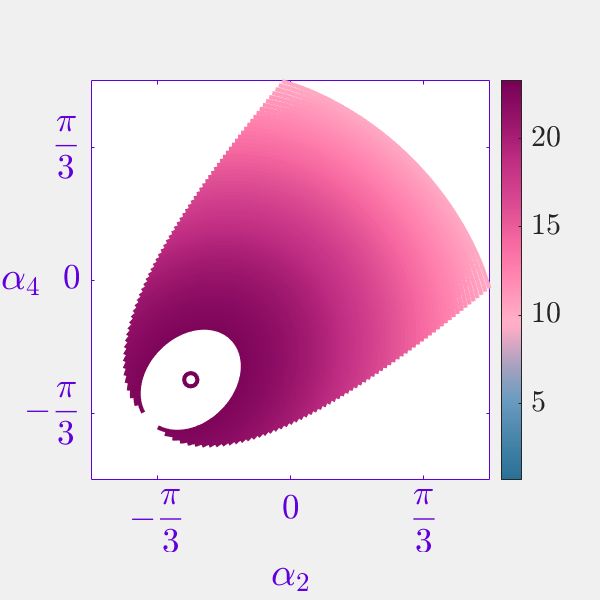

Path2_Mobility.highlightNonslipLevelSet(FRHLstance, zeros(1, 2))

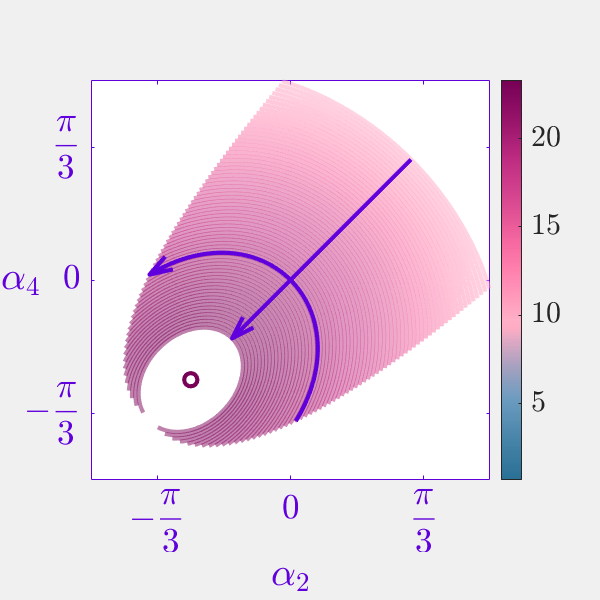

Path2_Mobility.highlightNonslipLevelSet(FLHRstance, zeros(1, 2))

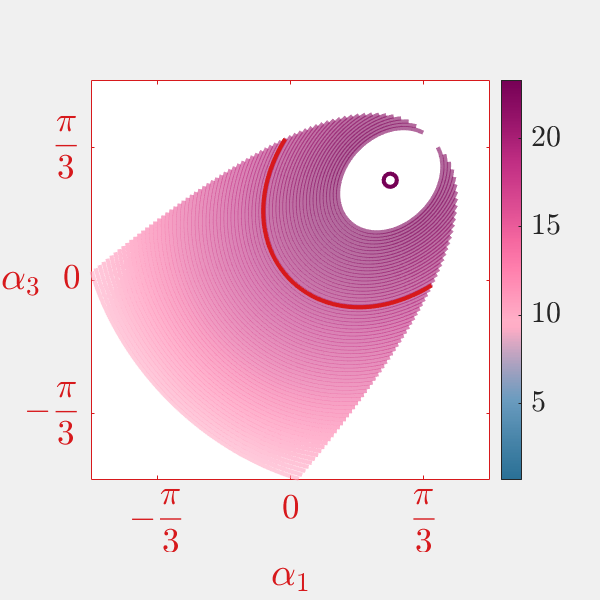

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;

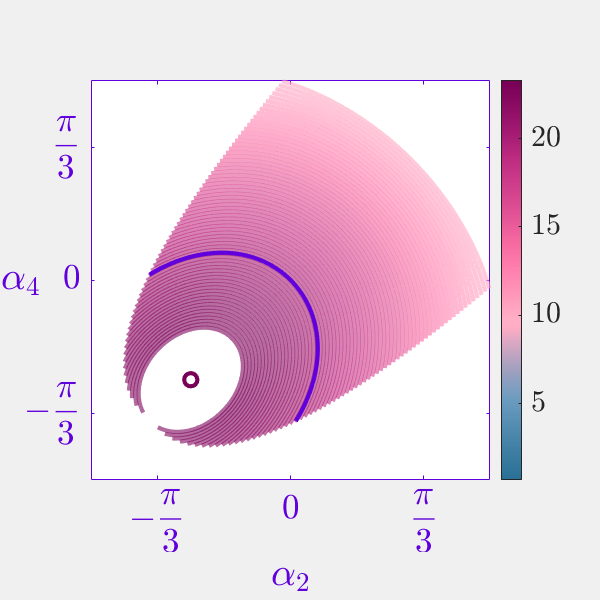

hamr6_F = false;

switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
load(dataName); load(dataMotPlanName);

Here, we obtain the information needed to reconstruct the scaling and sliding inputs from paper 2. This is required to compare the ground-truth trajectory information obtained by simulating the system forward.

% define the forward gait from paper 2
ref = []; 
ref.P = zeros(1, 2); ref.T = -0.8*ones(1, 2); % reference point and integration times to generate stance paths
inputs = [  [0, 0]', [1, 0]' ]; % columnwise inputs for each stance phase
% obtain the configuration trajectories during each stance phase
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory(ref, inputs(:, 1)', FRHLstance); % compute stance '13' trajectory
configTraj24 = Path2_Mobility.simulateConfigurationTrajectory(ref, inputs(:, 2)', FLHRstance); % compute stance '24' trajectory

Integrate the body velocity induced by the stance paths simultaneously to obtain a net displacement estimate. This should have the same structure as the stance paths in each contact submanifold. This is also the estimate obtained from naively integrating the stance phase panels: $\exp (dz_i + dz_j)$

jointStancePath = [];
jointStancePath.parameters.length = sqrt(configTraj13.parameters.Length^2 + configTraj24.parameters.Length^2); % get euclidean length
jointStancePath.parameters.disc = ceil(mean( [ jointStancePath.parameters.length/configTraj13.parameters.Length*configTraj13.parameters.disc, ...
                    jointStancePath.parameters.length/configTraj24.parameters.Length*configTraj24.parameters.disc] ));
% COMPLETE CASE
jointStancePath.complete.T = linspace(0, jointStancePath.parameters.length, numel(configTraj13.complete.t))'; % ... complete time vector for the joint path
jointStancePath.complete.t = [configTraj13.complete.t, configTraj24.complete.t]; % ... individual time vectors for each path
jointStancePath.complete.r = [configTraj13.complete.r, configTraj24.complete.r]; % ... complete shape trajectory
jointStancePath.complete.dz = [configTraj13.complete.dz, configTraj24.complete.dz]; % ... complete stratified panel (sum of the panels in each stance)
jointStancePath.complete.gHat = configTraj13.complete.gHat + configTraj24.complete.gHat; % .. complete body trajectory estimate
jointStancePath.complete.zHat = jointStancePath.gHat(end, :)'; % ... net displacement
% DISCRETIZED CASE
jointStancePath.discretized.T = linspace(0, jointStancePath.parameters.length, jointStancePath.parameters.disc)';
% ... STANCE 13
switch configTraj13.parameters.disc % number time steps
    case 1 % if only one point, then repeat the values at all time steps
        jointStancePath.discretized.t(:, 1) = repmat(configTraj13.discretized.t, jointStancePath.parameters.disc, 1); 
        jointStancePath.discretized.r(:, 1:2) = repmat(configTraj13.discretized.r, jointStancePath.parameters.disc, 1); 
        jointStancePath.discretized.dz(:, 1) = repmat(configTraj13.discretized.dz, jointStancePath.parameters.disc, 1); 
        jointStancePath.discretized.gHat = repmat(configTraj13.discretized.gHat, jointStancePath.parameters.disc, 1);
    otherwise
        jointStancePath.discretized.t(:, 1) = interp1((1:configTraj13.parameters.disc)', configTraj13.discretized.t,...
                            linspace(1, configTraj13.parameters.disc, jointStancePath.parameters.disc)', "linear");
        switch configTraj13.parameters.disc
            case 2 % if two steps, linearly interpolate at all intermediate time steps
                interpMethod = 'linear';
            case 3
                interpMethod = 'linear';
            otherwise % if four or more steps, 'pchip' interpolate at all intermediate time steps
                interpMethod = 'pchip';
        end 
        jointStancePath.discretized.r(:, 1:2) = interp1(configTraj13.complete.t, configTraj13.complete.r,...
                                            jointStancePath.discretized.t(:, 1), interpMethod); 
        jointStancePath.discretized.dz(:, 1) = interp1(configTraj13.complete.t, configTraj13.complete.dz,...
                                            jointStancePath.discretized.t(:, 1), interpMethod); 
        jointStancePath.discretized.gHat = interp1(configTraj13.complete.t, configTraj13.complete.gHat,...
                                            jointStancePath.discretized.t(:, 1), interpMethod); 
end
% ... STANCE 24
switch configTraj24.parameters.disc % number time steps
    case 1 % if only one point, then repeat the values at all time steps
        jointStancePath.discretized.t(:, end+1) = repmat(configTraj13.discretized.t, jointStancePath.parameters.disc, 1); 
        jointStancePath.discretized.r(:, end+(1:2)) = repmat(configTraj13.discretized.r, jointStancePath.parameters.disc, 1); 
        jointStancePath.discretized.dz(:, end+1) = repmat(configTraj13.discretized.dz, jointStancePath.parameters.disc, 1); 
        jointStancePath.discretized.gHat = jointStancePath.discretized.gHat + ...
                                        repmat(configTraj13.discretized.gHat, jointStancePath.parameters.disc, 1);
    otherwise
        jointStancePath.discretized.t(:, end+1) = interp1((1:configTraj13.parameters.disc)', configTraj13.discretized.t,...
                            linspace(1, configTraj13.parameters.disc, jointStancePath.parameters.disc)', "linear");
        switch configTraj13.parameters.disc
            case 2 % if two steps, linearly interpolate at all intermediate time steps
                interpMethod = 'linear';
            case 3
                interpMethod = 'linear';
            otherwise % if four or more steps, 'pchip' interpolate at all intermediate time steps
                interpMethod = 'pchip';
        end 
        jointStancePath.discretized.r(:, end+(1:2)) = interp1(configTraj13.complete.t, configTraj13.complete.r,...
                                            jointStancePath.discretized.t(:, 1), interpMethod); 
        jointStancePath.discretized.dz(:, end+1) = interp1(configTraj13.complete.t, configTraj13.complete.dz,...
                                            jointStancePath.discretized.t(:, 1), interpMethod); 
        jointStancePath.discretized.gHat = jointStancePath.discretized.gHat + ...
                                        interp1(configTraj13.complete.t, configTraj13.complete.gHat,...
                                            jointStancePath.discretized.t(:, 1), interpMethod); 
end
% ... NET DISPLACEMENT
jointStancePath.discretized.zHat = jointStancePath.discretized.gHat(end, :)';

Compute the actual body trajectory of the system by integrating the velocity in a rest frame coincident with the body frame at the beginning of the gait cycle.

g13 = configTraj13.complete.g; z13 = g13(end, :)'; % stance 13 body trajectory and net displacement
g24 = configTraj24.complete.g; z24 = g24(end, :)'; % stance 24 ...
gb = [ g13(1:end-1, :); % overall body trajectory: stance 13 until last point
    (repmat(z13, 1, size(g24, 1)) + ... % ... : add the stance 13 displacement
                        rot_SE2(z13(3))*g24')' ]; % ... : shift stance 24 trajectory into the body frame
zb = z13 + rot_SE2(z13(3))*z24; % ... : overall net displacement

Let's visualize the body trajectory with the naive stance path estimate for comparison

b = gb; fS = 25; gbCol = [31,120,180]/255; % 'Visible', 'on', 
figure('Units', 'pixels', 'Position', [0 0 600 600]); ax = gca; box(ax, "on");
% plot the body trajectory, represent the net displacement, and the body
% orientation
plot(ax, b(:, 1), b(:, 2), '-', 'LineWidth', 2.0, 'Color', gbCol);
grid(ax, "on"); hold(ax, "on"); set(ax,'TickLabelInterpreter','latex');
scatter(ax, zb(1), zb(2), 100, 'o', "filled", "MarkerFaceColor", gbCol, 'MarkerFaceAlpha', 1.00);
quiver(ax, zb(1),  zb(2), -sin(zb(3)), cos(zb(3)),...
    'LineWidth', 3.0, 'Color', gbCol, 'LineStyle', '-',...
    'AutoScaleFactor', 0.5);
% plot the naive integral of the stratified panels
plot(ax, jointStancePath.discretized.gHat(:, 1), jointStancePath.discretized.gHat(:, 2),...
                                    '--', 'LineWidth', 2.0, 'Color', [ [0, 0, 0]/255, 0.25 ]);
scatter(ax, jointStancePath.discretized.zHat(1), jointStancePath.discretized.zHat(2), 100, 'o', "filled",...
                            "MarkerFaceColor", [0, 0, 0]/255, 'MarkerFaceAlpha', 1.00);
axis(ax, "equal", "padded"); ax.FontSize = fS;
xlabel('$$x$$', 'FontSize', fS, 'Interpreter', 'latex');
ylabel('$$y$$', 'FontSize', fS, 'Interpreter', 'latex'); 

We now compute the lie-bracket of the stratified panels involved in $S_{13}$ and $S_{24}$.

Goal is to estimate the noncommutativity generated by out two-beat contact-switching trot gait and for this we represent gait cycle as a function of the stance phase paths in each contact state.

FRHLstance.aParaRef

ans = struct with fields:
      isValid: 1
    eventInfo: {''  ''}
            y: [101×2 double]
            t: [101×1 double]
           dz: [101×3 double]
        color: [0.6639 0.1221 0.4597]


FLHRstance.aParaRef

ans = struct with fields:
      isValid: 1
    eventInfo: {''  ''}
            y: [101×2 double]
            t: [101×1 double]
           dz: [101×3 double]
        color: [0.6639 0.1221 0.4597]


Here's a quick and dirty way of visualizing the lie-bracket that encodes the noncommutativity.

t13 = FRHLstance.aParaRef.t - 1.2; t24 = FLHRstance.aParaRef.t - 1.2;
[t13, t24] = meshgrid(t13, t24); 
dz13 = interp1(FRHLstance.aParaRef.t, FRHLstance.aParaRef.dz, reshape(t13, [numel(t13), 1]), "pchip");
dz24 = interp1(FLHRstance.aParaRef.t, FLHRstance.aParaRef.dz, reshape(t24, [numel(t24), 1]), "pchip");

% reshaping componentwise and rewrite vars
temp13__x = reshape(dz13(:, 1), size(t13)); 
    temp13__y = reshape(dz13(:, 2), size(t13)); 
        temp13__th = reshape(dz13(:, 3), size(t13));
            dz13 = nan([size(t13), 3]);
            dz13(:, :, 1) = temp13__x; 
                dz13(:, :, 2) = temp13__y; 
                    dz13(:, :, 3) = temp13__th;
temp24__x = reshape(dz24(:, 1), size(t24)); 
    temp24__y = reshape(dz24(:, 2), size(t24)); 
        temp24__th = reshape(dz24(:, 3), size(t24));
            dz24 = nan([size(t13), 3]);
            dz24(:, :, 1) = temp24__x; 
                dz24(:, :, 2) = temp24__y; 
                    dz24(:, :, 3) = temp24__th;

Now, we have all the components we need to compute the first order (or even nth order lie-brackets). We shall only focus on the first-order for this stuff.

% compute the lie-brackets componentwise (has only x and y components)
dzLieB_13_14__x = dz13(:, :, 2).*dz24(:, :, 3) - dz24(:, :, 2).*dz13(:, :, 3); 
dzLieB_13_14__y = dz24(:, :, 1).*dz13(:, :, 3) - dz13(:, :, 1).*dz24(:, :, 3);

Now, we make quick figures after defining our colormap.

% colormap
CUB = flipud([159.3750,99.6030,63.4312;
          239.0625,149.4045,95.1469;
          255.0000,199.2060,126.8625;
            204,204,204;
            150,150,150;
            99,99,99])/255;
CUB = interp1(linspace(0,100,size(CUB,1)), CUB, linspace(0,100,size(turbo,1)));
% color limits for the plot
lieColorLimits = [min([min(dzLieB_13_14__x, [], "all") min(dzLieB_13_14__y, [], "all")]),...
                  max([max(dzLieB_13_14__x, [], "all") max(dzLieB_13_14__y, [], "all")])]; 

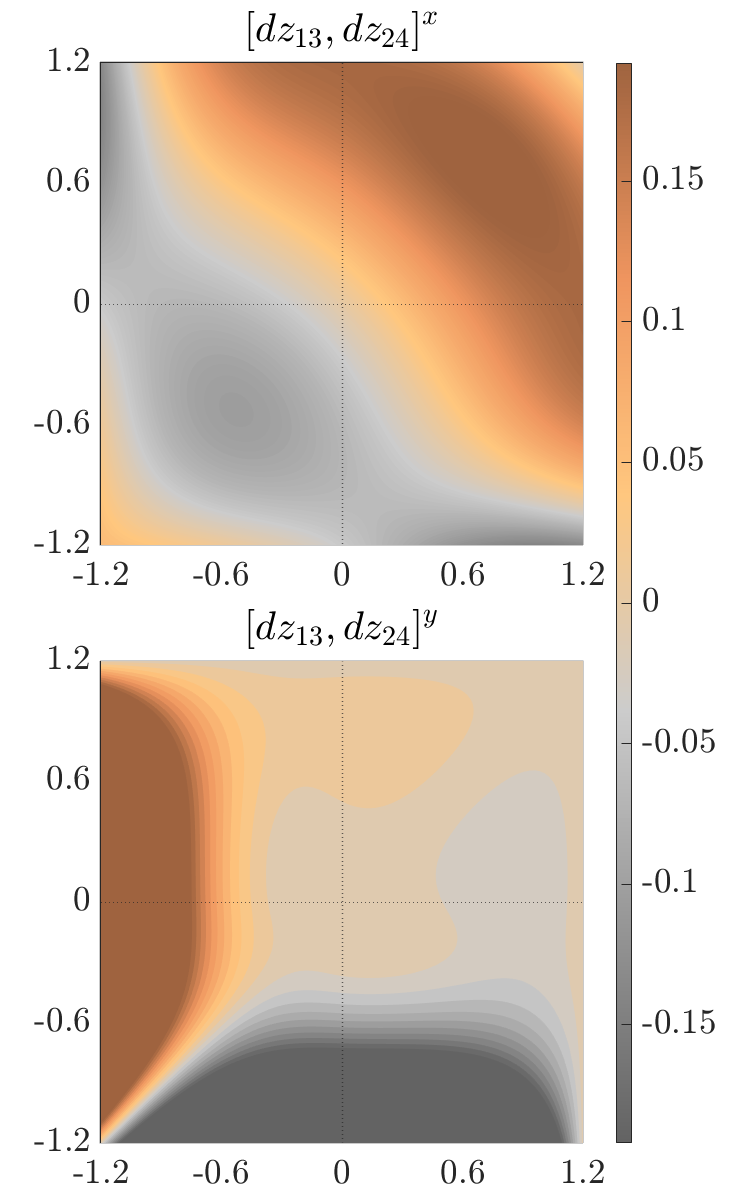

mul = 0.20;
f = figure('units', 'pixels', 'position', [0 0 750 1200], 'Color','w'); set(f,'Visible','on');
tl = tiledlayout(f, 2, 1, "TileSpacing", "compact", "Padding", "compact");

ax = nexttile(tl); hold(ax, "on"); box(ax, "on"); ax.LineWidth = 1.2;
contourf(ax, t13, t24, dzLieB_13_14__x, 100, 'LineStyle', 'none');
xline(0, ':', LineWidth=1.2); yline(0, ':', LineWidth=0.8); xticks(-1.2:0.6:1.2); yticks(-1.2:0.6:1.2);
plot();
ax.FontSize = 26.5; clim(ax, mul*lieColorLimits); colormap(ax, CUB); axis(ax, "equal", "tight");
title(ax, '$$[dz_{13}, dz_{24}]^x$$', 'FontSize', 30);

ax = nexttile(tl); hold(ax, "on"); box(ax, "on"); ax.LineWidth = 1.2;
contourf(t13, t24, dzLieB_13_14__y, 100, 'LineStyle', 'none');
xline(0, ':', LineWidth=1.2); yline(0, ':', LineWidth=0.8); xticks(-1.2:0.6:1.2); yticks(-1.2:0.6:1.2);
plot();
ax.FontSize = 26.5; clim(ax, mul*lieColorLimits); colormap(ax, CUB); axis(ax, "equal", "tight");
title(ax, '$$[dz_{13}, dz_{24}]^y$$', 'FontSize', 30);

cBar = colorbar(); cBar.Layout.Tile = 'East'; cBar.TickLabelInterpreter = 'latex'; cBar.FontSize = 26.5;